# Problema 1 - Suplimentar

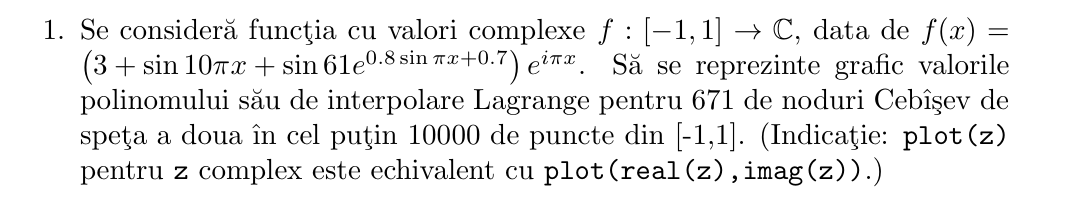

%PB1
function p_val = lagrangeInterpolation(x_nodes, y_nodes, x_eval)
    n = length(x_nodes);
    p_val = zeros(size(x_eval));
    for k = 1:length(x_eval)
        xk = x_eval(k);
        Lk = ones(1, n);
        for i = 1:n
            for j = 1:n
                if j ~= i
                    Lk(i) = Lk(i) * (xk - x_nodes(j)) / (x_nodes(i) - x_nodes(j));
                end
            end
        end
        p_val(k) = sum(Lk .* y_nodes);
    end
end

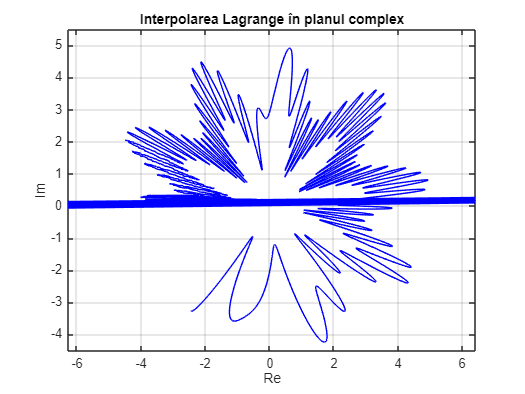

n = 671;
j = 0:n-1;
x_nodes = cos(pi * j / (n - 1));
f = @(x) (3 + sin(10*pi*x) + sin(61 * exp(0.8 * sin(pi*x) + 0.7))) .* exp(1i * pi * x);
y_nodes = f(x_nodes);
x_eval = linspace(-1, 1, 10000);
p_eval = lagrangeInterpolation(x_nodes, y_nodes, x_eval);

% Reprezentare grafică
figure;
plot(real(p_eval), imag(p_eval), 'b');
title('Interpolarea Lagrange în planul complex');
xlabel('Re');
ylabel('Im');
grid on;
axis equal;